8.1

Consider to the 'Law of mass action'.

As for the reaction rate:


$$$$
A \stackrel{k_1}{\longrightarrow} B \\
r=\frac{-d[A]}{d t}=\frac{d[B]}{d t} \\
r=k_1[A]
$$$$


where $$k_1$$ is a rate constant.

As for the eeversible rate:


$$$$
A \underset{k_2}{\stackrel{k_1}{\rightleftharpoons}} B \\
r=\frac{-d[A]}{d t}=\frac{d[B]}{d t} \\
r=k_1[A]-k_{2}[B]
$$$$


When the reaction is in equilibrium:


$$$$
r=0 \\
k_1[A]=k_{2}[B] \\
\frac{k_{2}}{k_1}=\frac{[A]}{[B]}=K_{e q}
$$$$


Now, consider to the Enzyme‐catalyzed reactions.

First step: E forms a complex with S to form an intermediate species ES in a reversible manner at the forward rate k1 and reverse rate k2.


$$$$
S+E \underset{k_2}{\stackrel{k_1}{\rightleftharpoons}} ES
$$$$


In the Law of Mass Action, we assume that the rate of forward reaction is linearly proportional to the concentrations of S and E, and the back reaction is linearly proportional to the concentration of ES:


$$$$
r=k_1[S][E]-k_{2}[ES] 
$$
$$


Second step：The intermediate ES then breaks down into the product P at a rate k3,thereby releasing E.


$$$$
ES \stackrel{k_3}{\longrightarrow} E+P 
$$$$


Then,


$$$$
r=\frac{d[P]}{d t}=k_3[E S]
$$$$


Since the concentration of ES affects both the first step reaction and the second step reaction, we have：


$$$$
\frac{d[S]}{d t}=-k_1[E][S]+k_{2}[E S] \\
\frac{d[E]}{d t}=-k_1[E][S]+k_{2}[E S]+k_{3}[E S] \\
\frac{d[E S]}{d t}=k_1[E][S]-k_{2}[E S]-k_3[E S] \\
\frac{d[P]}{d t}=k_3[E S]
$$$$


8.2

From the solution of 8.1, we have:


$$$$
\frac{d[S]}{d t}=-k_1[S][E]+k_{2}[E S] \\
\frac{d[E]}{d t}=-k_1[S][E]+k_{2}[E S]+k_3[E S] \\
\frac{d[E S]}{d t}=k_1[S][E]-k_{2}[E S]-k_3[E S] \\
\frac{d[P]}{d t}=k_3[E S]\
$$$$


with the initial conditions:


$$$$
[S]_0=10 \mu \mathrm{M} \quad[E]_0=1 \mu \mathrm{M} \quad[E S]_0=0 \quad[P]_0=0
$$$$


and the constants:


$$$$
k_1=100(\mu \mathrm{M})^{-1} \mathrm{~min}^{-1}\approx 1.67(\mu \mathrm{M})^{-1} \mathrm{~s}^{-1}  \\ k_{2}=600 \mathrm{~min}^{-1} =10\mathrm{~s}^{-1}  \\
k_3=150 \mathrm{~min}^{-1}=2.5\mathrm{~s}^{-1} 
$$$$


clc; 
clear all;
% Set the initial conditions, constants, & time span
yzero=[10, 1, 0, 0];
k1=1.67; k2=10; k3=2.5;
tspan=[0 30]; 

% Integrate the equations
[t,y]=ode45('E_K_equations',tspan,yzero,[],k1,k2,k3);

% Print out the results
n=length(y);
for i=1:n
    if y(i,1)<=0.001*yzero(1)
    fprintf('Reaction is 99.9 percent complete at time = %4.0f seconds',t(i));
    break
    end
end

Reaction is 99.9 percent complete at time =   26 seconds

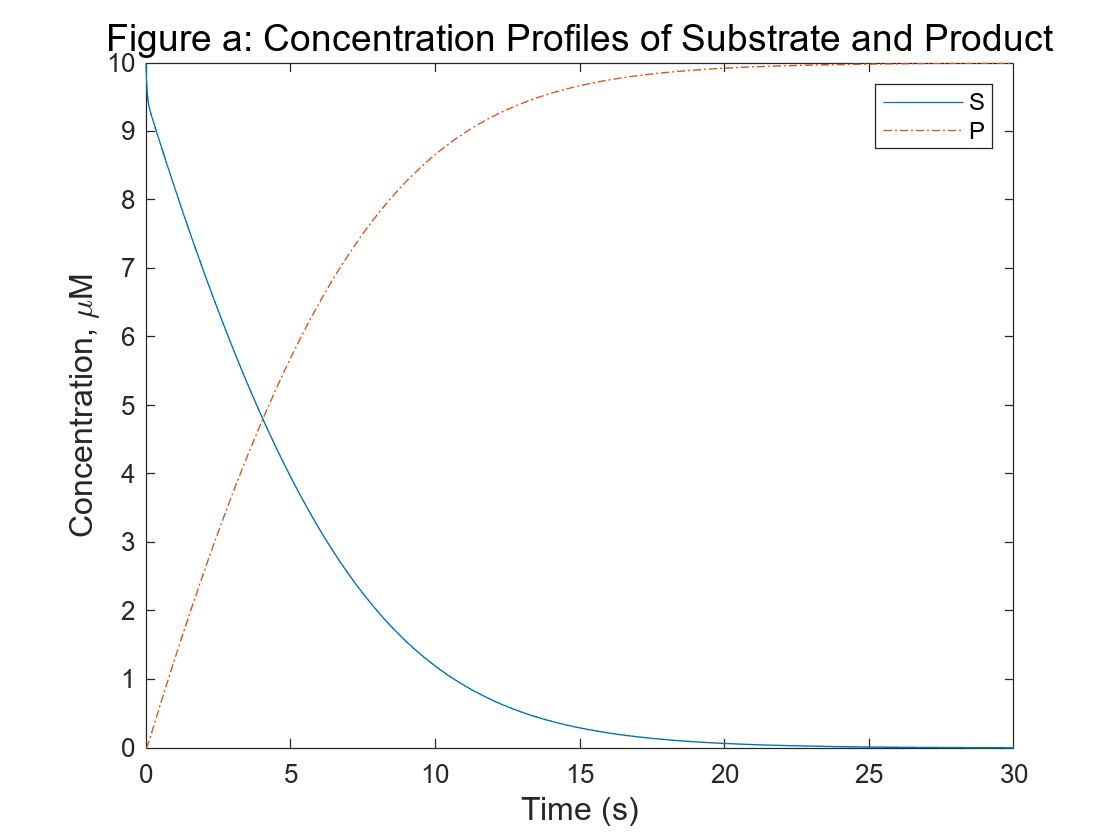

% Plot concentration profiles
clf; figure(1); plot(t,y(:,1),'-',t,y(:,4),'-.')
title('Figure a: Concentration Profiles of Substrate and Product', 'FontSize',14)
xlabel('Time (s)','FontSize',12);
ylabel('Concentration, \muM', 'FontSize',12);
legend('S','P');

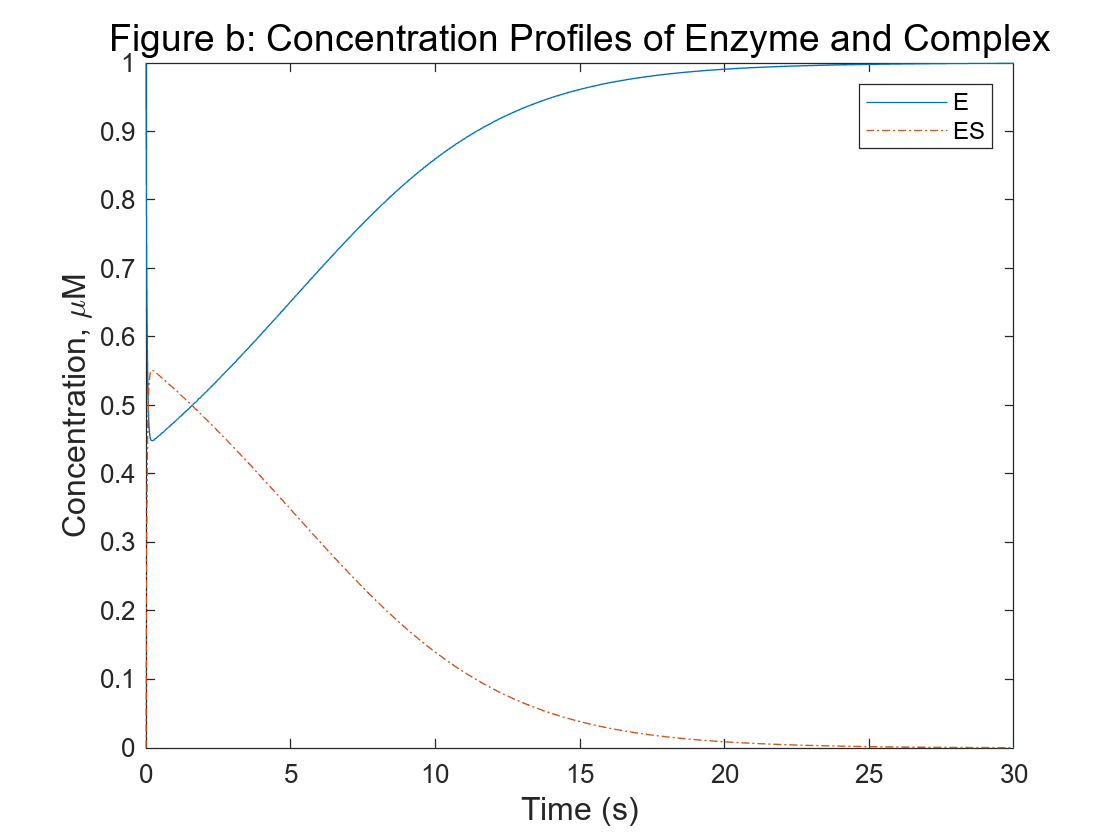

figure(2); plot(t,y(:,2),'-',t,y(:,3),'-.')
title('Figure b: Concentration Profiles of Enzyme and Complex', 'FontSize',14)
xlabel('Time (s)','FontSize',12);
ylabel('Concentration, \muM', 'FontSize',12);
legend('E','ES') 

8.3

Since the velocity, V, of the enzymatic reaction to be the rate of change of the product P. From 8.1 we know:


$$$$
V=\frac{d[P]}{d t}=k_3[E S]
$$
$$


At steady state:


$$$$
k_1[E][S]=k_{2}[E S]+k_3[E S]
$$$$


Hence we have：


$$$$
[E S]=[E][S] \frac{k_1}{k_{2}+k_3}
$$$$


Define:


$$$$
K_M=\frac{k_{2}+k_3}{k_1}
$$$$


At the beginning of the reaction, the concentration of E is the highest, so the reaction rate is also the largest. In the process of subsequent reaction, the sum of the concentration of E and ES is a certain value, we define as:


$$$$
{[E]_t=[E]+[E S]} \\
V_{\max }=k_3[E]_t
$$$$


Thus,we can conclude:$$$
[E S]=[E]_t \frac{[S]}{K_M+[S]} \\
V=k_3[E S]=k_3[E]_t \frac{[S]}{K_M+[S]}=V_{\max } \frac{[S]}{K_M+[S]}
$$$

KM=(k2+k3)/k1;
Vmax=k3*yzero(2);
V=zeros(1,n);
S=linspace(1,250,n)

S =     1.0000    1.3843    1.7685    2.1528    2.5370    2.9213    3.3056    3.6898    4.0741    4.4583    4.8426    5.2269    5.6111    5.9954    6.3796    6.7639    7.1481    7.5324    7.9167    8.3009    8.6852    9.0694    9.4537    9.8380   10.2222   10.6065   10.9907   11.3750   11.7593   12.1435   12.5278   12.9120   13.2963   13.6806   14.0648   14.4491   14.8333   15.2176   15.6019   15.9861   16.3704   16.7546   17.1389   17.5231   17.9074   18.2917   18.6759   19.0602   19.4444   19.8287


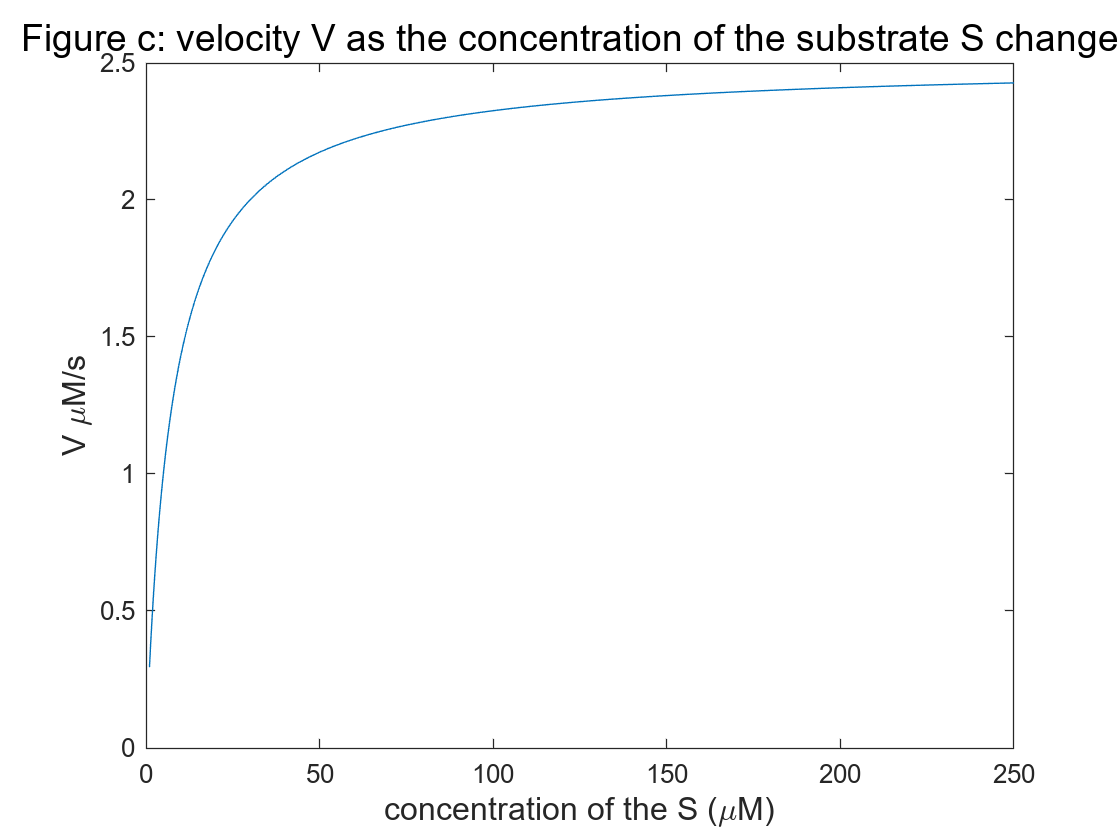

for i=1:n
    V(1,i)=Vmax*S(i)/(KM+S(i));
end

clf; figure(3); plot(S(:),V(1,:),'-')
title('Figure c: velocity V as the concentration of the substrate S changes', 'FontSize',14)
xlabel('concentration of the S (\muM)','FontSize',12);
ylabel('V \muM/s', 'FontSize',12);

fprintf('The maximum value of velocity V is %0.2f muM/s.',Vmax);

The maximum value of velocity V is 2.50 muM/s